%% ==========================================================
%  DIRECT (NON-RECURSIVE) MULTI-STEP + 1-STEP BASELINE
%  - keeps your feature engineering exactly as-is
%  - trains:
%      (A) 1-step RT + 1-step RF  (same as your baseline)
%      (B) 20 separate RF models for horizons h=1..20 (DIRECT)
%  - evaluates and plots:
%      - 1-step teacher forcing (RT/RF)
%      - direct 20-step (h=20) vs actual
%      - RMSE vs horizon (1..20)
% ===========================================================

%% =========================
%  0) Load data
% =========================
filename = 'SONICATEL traffic train.csv';
T = readtable(filename);

vars = T.Properties.VariableNames;

req = {'dayweek','hour','Netflix'};
for i=1:numel(req)
    if ~ismember(req{i}, vars)
        error('Missing column: %s', req{i});
    end
end

dayweek = double(T.dayweek);
hour    = double(T.hour);

use_extra = all(ismember({'IN','OUT','VOIP'}, vars));
if use_extra
    IN   = double(T.IN);
    OUT  = double(T.OUT);
    VOIP = double(T.VOIP);
else
    warning('IN/OUT/VOIP not found -> using only time + Netflix lags');
end

Netflix = double(T.Netflix);

%% =========================
%  1) Feature extraction (same as you)
% =========================
d = 12;
use_daily_lag = true;
dailyLag = 288;

N = length(Netflix);

start_k = d + 1;
if use_daily_lag
    start_k = max(start_k, dailyLag + 1);
end

nSamples = N - start_k + 1;

p_time = 2;
p_extra = 0;
if use_extra, p_extra = 3; end
p_lags  = d;
p_daily = double(use_daily_lag);

P = p_time + p_extra + p_lags + p_daily;

X = zeros(nSamples, P);
Y = zeros(nSamples, 1);

for k = start_k:N
    idx = k - start_k + 1;

    col = 1;
    X(idx,col) = dayweek(k); col = col+1;
    X(idx,col) = hour(k);    col = col+1;

    if use_extra
        X(idx,col) = IN(k);   col = col+1;
        X(idx,col) = OUT(k);  col = col+1;
        X(idx,col) = VOIP(k); col = col+1;
    end

    X(idx, col:col+d-1) = Netflix(k-1:-1:k-d);
    col = col + d;

    if use_daily_lag
        X(idx, col) = Netflix(k-dailyLag);
        col = col + 1;
    end

    Y(idx) = Netflix(k);
end

Y_log = log1p(Y);

%% ==========================================================
%  2) DIRECT multi-step setup (make 20 targets WITHOUT recursion)
% ==========================================================
Hmax = 20;

% For direct models, we need Y_log shifted by +h.
% We can only use rows 1..(end-Hmax) so that Y(idx+h) exists.
N_total = size(X,1);
N_use = N_total - Hmax;

X_base   = X(1:N_use, :);
Ylog_all = Y_log;                 % keep full for shifting

%% =========================
%  3) Train/test split (time order) on X_base
% =========================
N_train = floor(0.8 * N_use);

X_train = X_base(1:N_train,:);
X_test  = X_base(N_train+1:end,:);

% Normalize using TRAIN stats
min_vals = min(X_train, [], 1);
max_vals = max(X_train, [], 1);
range_vals = max_vals - min_vals;
range_vals(range_vals==0) = 1;

X_train_norm = (X_train - min_vals) ./ range_vals;
X_test_norm  = (X_test  - min_vals) ./ range_vals;

%% =========================
%  4) Train 1-step models (baseline)  (h = 1)
% =========================
maxDepth = 12;
minLeaf  = 2;

% 1-step target aligned with X_base:
% X_base(i,:) corresponds to original Y_log(i)
% For 1-step ahead, we want target = Y_log(i+1)
Y1_log = Ylog_all(2 : N_use+1);

Y1_train = Y1_log(1:N_train);
Y1_test  = Y1_log(N_train+1:end);

% Single tree (RT) baseline for 1-step
mtry_tree = size(X_train_norm,2);
modelTree_1 = buildTree(X_train_norm, Y1_train, 0, maxDepth, minLeaf, mtry_tree);

% Random forest (RF) baseline for 1-step
nTrees = 80;
p = size(X_train_norm,2);
mtry_rf = max(2, floor(sqrt(p)));

forest_1 = cell(nTrees,1);
rng(1);
Ntr = size(X_train_norm,1);

for t=1:nTrees
    boot = randi(Ntr, Ntr, 1);
    forest_1{t} = buildTree(X_train_norm(boot,:), Y1_train(boot), 0, maxDepth, minLeaf, mtry_rf);
end

%% =========================
%  5) Evaluate 1-step models (teacher forcing baseline)
% =========================
Hplot = 200;
Hplot = min(Hplot, length(Y1_test));

pred_tree_1_log = predictTree(modelTree_1, X_test_norm(1:Hplot,:));

pred_rf_1_log = zeros(Hplot,1);
for t=1:nTrees
    pred_rf_1_log = pred_rf_1_log + predictTree(forest_1{t}, X_test_norm(1:Hplot,:));
end
pred_rf_1_log = pred_rf_1_log / nTrees;

Y1_actual_raw = expm1(Y1_test(1:Hplot));
tree_raw_1    = expm1(pred_tree_1_log);
rf_raw_1      = expm1(pred_rf_1_log);

rmse_tree_1 = sqrt(mean((tree_raw_1 - Y1_actual_raw).^2));
rmse_rf_1   = sqrt(mean((rf_raw_1   - Y1_actual_raw).^2));
fprintf('DIRECT 1-step RMSE (raw): RT = %.3f, RF = %.3f\n', rmse_tree_1, rmse_rf_1);

DIRECT 1-step RMSE (raw): RT = 24424922.753, RF = 15210672.250



%% ==========================================================
%  6) Train DIRECT 20 models (RF only) for horizons h=1..20
%      Each horizon has its own forest forestH{h}
% ==========================================================
forestH = cell(Hmax,1);

for h = 1:Hmax
    % horizon-h target aligned with X_base rows:
    % X_base(i,:) uses info up to time k (your features),
    % target is Y_log(i+h) = log(1+Y at k+h)
    Yh_log = Ylog_all(1+h : N_use+h);

    Yh_train = Yh_log(1:N_train);

    forest = cell(nTrees,1);
    for t=1:nTrees
        boot = randi(Ntr, Ntr, 1);
        forest{t} = buildTree(X_train_norm(boot,:), Yh_train(boot), 0, maxDepth, minLeaf, mtry_rf);
    end

    forestH{h} = forest;
end

%% =========================
%  7) Evaluate DIRECT horizons on the test set (no recursion)
% =========================
Nte = size(X_test_norm,1);

pred_direct_log = zeros(Nte, Hmax);
act_direct_log  = zeros(Nte, Hmax);

for h = 1:Hmax
    Yh_log = Ylog_all(1+h : N_use+h);
    Yh_test = Yh_log(N_train+1:end);     % aligned with X_test
    act_direct_log(:,h) = Yh_test;

    forest = forestH{h};
    s = zeros(Nte,1);
    for t=1:nTrees
        s = s + predictTree(forest{t}, X_test_norm);
    end
    pred_direct_log(:,h) = s / nTrees;
end

pred_direct_raw = expm1(pred_direct_log);
act_direct_raw  = expm1(act_direct_log);

% RMSE vs horizon
rmse_h = zeros(Hmax,1);
for h=1:Hmax
    rmse_h(h) = sqrt(mean((pred_direct_raw(:,h) - act_direct_raw(:,h)).^2));
end

fprintf('DIRECT RMSE horizons 1..20 (raw):\n');

DIRECT RMSE horizons 1..20 (raw):


disp(rmse_h');

   1.0e+07 *

    1.2971    1.3944    1.4249    1.4236    1.4314    1.5236    1.5041    1.5187    1.6183    1.6172    1.5858    1.6070    1.6050    1.6417    1.6515    1.6562    1.7807    1.7457    1.8082    1.7993



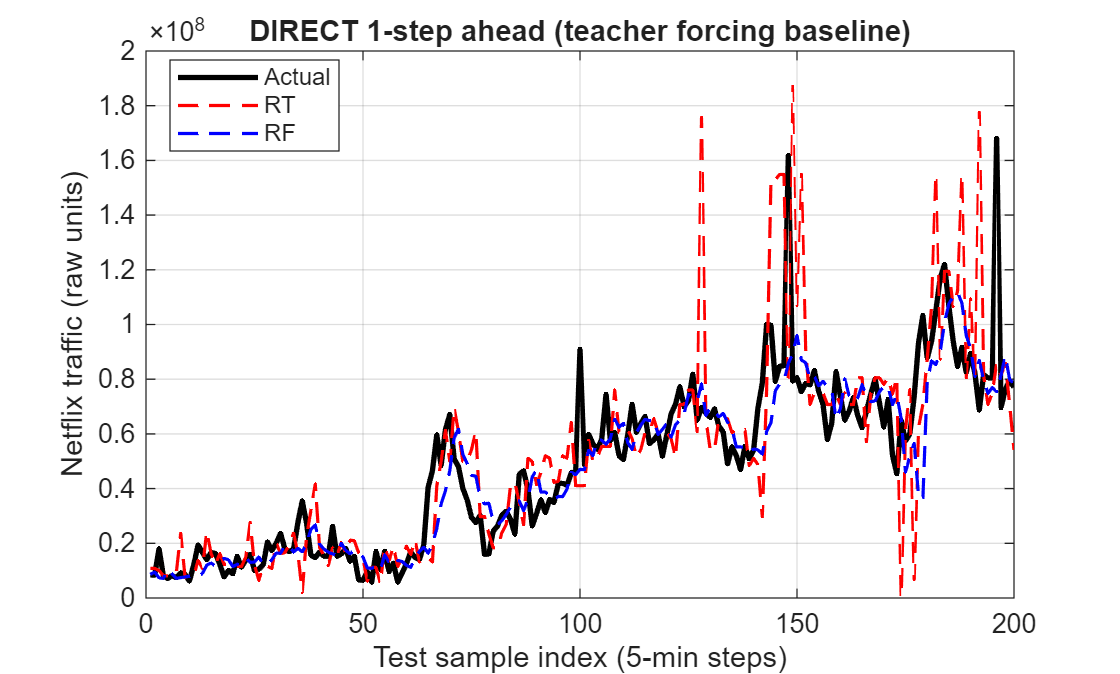


%% =========================
%  8) Plots
% =========================

% (A) 1-step teacher forcing plot (RT vs RF)
figure;
plot(1:Hplot, Y1_actual_raw, '-k', 'LineWidth', 2); hold on;
plot(1:Hplot, tree_raw_1, '--r', 'LineWidth', 1.2);
plot(1:Hplot, rf_raw_1,   '--b', 'LineWidth', 1.2);
grid on;
xlabel('Test sample index (5-min steps)');
ylabel('Netflix traffic (raw units)');
title('DIRECT 1-step ahead (teacher forcing baseline)');
legend('Actual','RT','RF','Location','best');

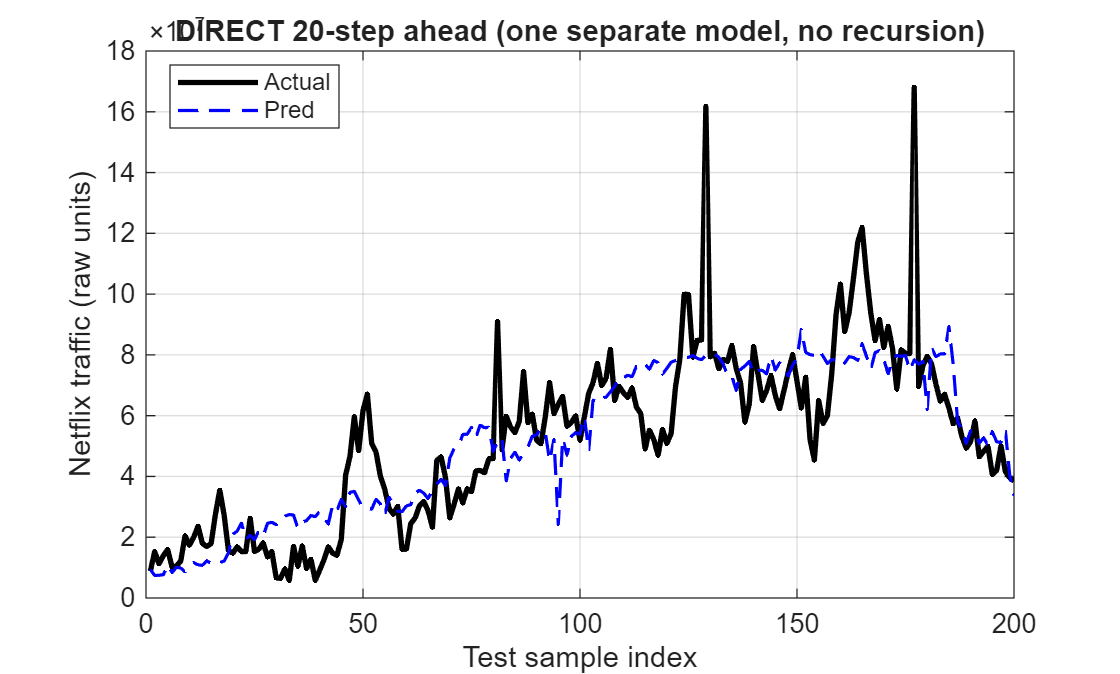


% (B) Direct 20-step plot (h = 20) over the first 200 test points
hshow = 20;
Hplot2 = min(200, Nte);

figure;
plot(1:Hplot2, act_direct_raw(1:Hplot2, hshow), '-k', 'LineWidth', 2); hold on;
plot(1:Hplot2, pred_direct_raw(1:Hplot2, hshow), '--b', 'LineWidth', 1.2);
grid on;
xlabel('Test sample index');
ylabel('Netflix traffic (raw units)');
title('DIRECT 20-step ahead (one separate model, no recursion)');
legend('Actual','Pred','Location','best');

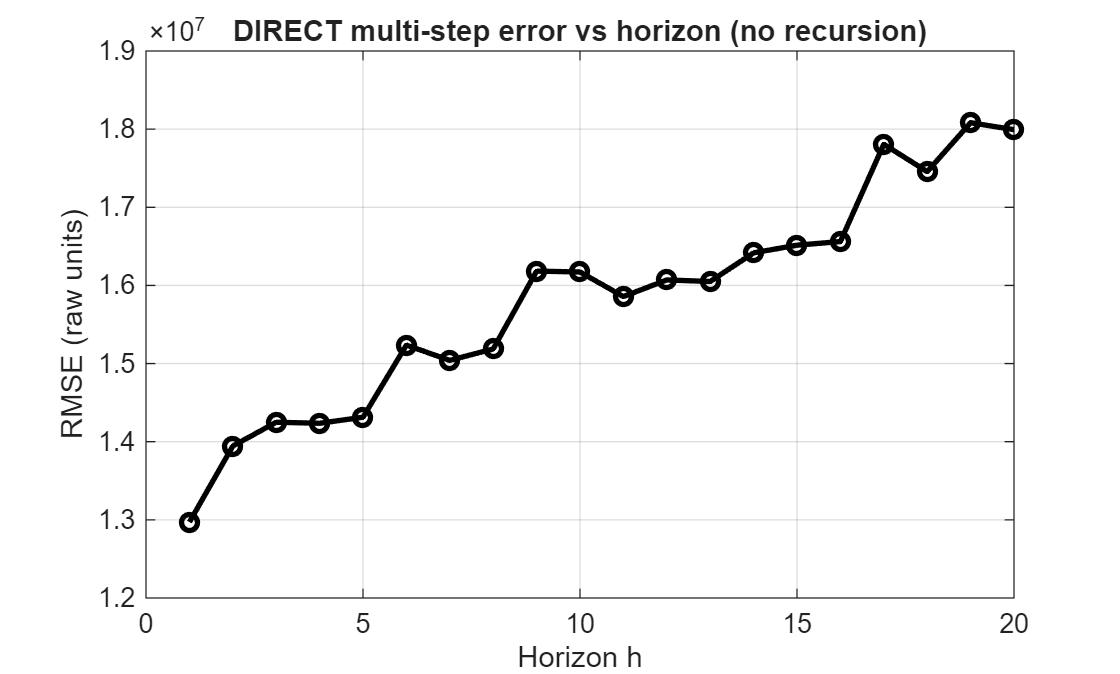


% (C) RMSE vs horizon
figure;
plot(1:Hmax, rmse_h, '-ko', 'LineWidth', 2);
grid on;
xlabel('Horizon h');
ylabel('RMSE (raw units)');
title('DIRECT multi-step error vs horizon (no recursion)');


%% =========================
%  Functions (same as yours)
% =========================
function tree = buildTree(X, Y, depth, maxDepth, minLeaf, mtry)
    tree = struct();
    n = size(X, 1);
    if depth >= maxDepth || n <= minLeaf
        tree.isLeaf = true;
        tree.prediction = mean(Y);
        return;
    end

    sumY = sum(Y);
    sumY2 = sum(Y.^2);
    currentError = sumY2 - (sumY^2)/n;

    bestError = currentError;
    bestFeat = -1;
    bestThresh = NaN;

    p = size(X, 2);
    if isempty(mtry) || mtry >= p
        featIdx = 1:p;
    else
        featIdx = randperm(p, mtry);
    end

    for j = featIdx
        [Xsorted, idx] = sort(X(:, j));
        Ysorted = Y(idx);
        cumY  = cumsum(Ysorted);
        cumY2 = cumsum(Ysorted.^2);

        for i = 1:(n-1)
            if Xsorted(i) == Xsorted(i+1), continue; end
            leftCount  = i;
            rightCount = n - i;

            leftSum  = cumY(i);
            leftSum2 = cumY2(i);
            rightSum  = sumY - leftSum;
            rightSum2 = sumY2 - leftSum2;

            errLeft  = leftSum2 - (leftSum^2)/leftCount;
            errRight = rightSum2 - (rightSum^2)/rightCount;
            totalErr = errLeft + errRight;

            if totalErr < bestError
                bestError = totalErr;
                bestFeat = j;
                bestThresh = (Xsorted(i) + Xsorted(i+1)) / 2;
            end
        end
    end

    if bestFeat == -1 || bestError >= currentError
        tree.isLeaf = true;
        tree.prediction = mean(Y);
        return;
    end

    tree.isLeaf = false;
    tree.feature = bestFeat;
    tree.threshold = bestThresh;

    leftIdx  = X(:, bestFeat) < bestThresh;
    rightIdx = ~leftIdx;

    tree.left  = buildTree(X(leftIdx, :),  Y(leftIdx),  depth+1, maxDepth, minLeaf, mtry);
    tree.right = buildTree(X(rightIdx, :), Y(rightIdx), depth+1, maxDepth, minLeaf, mtry);
end

function y_pred = predictTree(tree, X)
    n = size(X, 1);
    y_pred = zeros(n, 1);
    for i = 1:n
        node = tree;
        while ~node.isLeaf
            if X(i, node.feature) < node.threshold
                node = node.left;
            else
                node = node.right;
            end
        end
        y_pred(i) = node.prediction;
    end
end